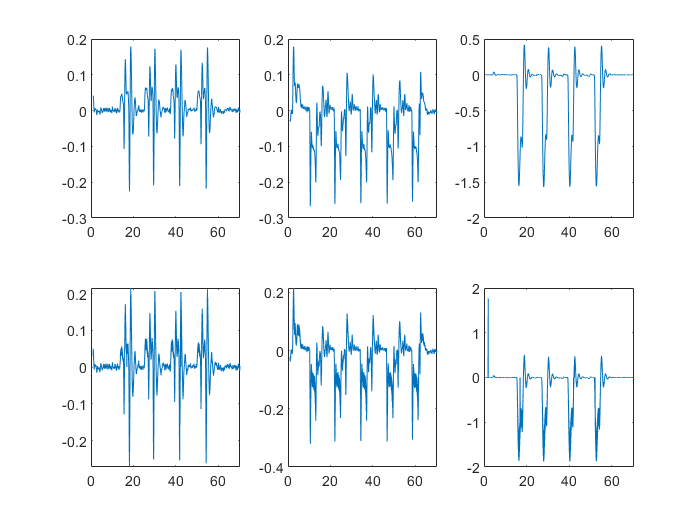

clear;
close all;

max_freq = 400;
reference_motor = 0.3; % 1300 pwm


%% Read test data
filename = 'Test3/00000282.csv';
test_data = csvread(filename, 2, 0);
refer_idx = find(test_data(:, 14) >= reference_motor, 1);
reference_time = test_data(refer_idx, 1); % test_data(1, 1)
test_data(:, 1) = test_data(:, 1)-reference_time; % reset start time
%trim data (remove unnecessary parts)
    isp = refer_idx + 1* max_freq;
    iep = find(test_data(:, 14) >= reference_motor,1,'last') - 2 * max_freq;
    test_data = test_data(isp:iep, :);

raw_timestamps = test_data(:,1) * 1e-6;    %(s)    time vector
time_us = test_data(:,1);
raw_states = test_data(:,2:13);            % array of state vector: 12 states
raw_motors = (((test_data(:,14:17)*1000)+1000)-1100)/900;   %SITL: (((0.5595*1000)+1000)-1100)/900=0.51
N = size(test_data,1);                 % size of samples
%========== to ENU ==============
% x <-> y, vx <-> vy
temp = raw_states(:,1); 
raw_states(:,1) = raw_states(:,2);
raw_states(:,2) = temp;
temp = raw_states(:,7); 
raw_states(:,7) = raw_states(:,8);
raw_states(:,8) = temp;
% z <-> -z, vz <-> -vz
raw_states(:,3) = -raw_states(:,3);
raw_states(:,9) = -raw_states(:,9);
% pitch <-> -pitch yaw = (-yaw + pi/2)
raw_states(:,5) = -raw_states(:,5);
raw_states(:,6) = mod(-raw_states(:,6)+pi/2, 2*pi);
% q <-> -q r <-> -r
raw_states(:,11) = -raw_states(:,11);
raw_states(:,12) = -raw_states(:,12);
%================================

euler_angles = raw_states(:, 4:6);
angular_speed = raw_states(:, 10:12);

gyro_reading = getGyroFromEuler(euler_angles, raw_timestamps);
figure;
for i=1:3
    subplot(2,3,i);
    plot(raw_timestamps(:), angular_speed(:, i));
    subplot(2,3,i+3);
    plot(raw_timestamps(1:end-1), gyro_reading(:, i));
end

function gyro_reading = getGyroFromEuler(euler_angles, time)
    d_euler_angles = diff(euler_angles) ./ diff(time);
    N = size(euler_angles, 1);
    gyro_reading = zeros(N-1, 3);
    for i = 1:N-1
        phi = euler_angles(i, 1);
        theta = euler_angles(i, 2);
        psi = euler_angles(i, 3);
        W_mat = [1, 0, -sin(theta); 
            0, cos(phi), cos(theta)*sin(phi); 
            0, -sin(phi), cos(phi)*cos(theta)];
        gyro_reading(i, :) = (W_mat * d_euler_angles(i, :)')';
        gyro_reading(i, abs(gyro_reading(i, :)) > 2*pi) = 0;
    end
end

function euler_angle = getEulerFromGyro(gyro, time)
euler_angle = zeros(size(gyro, 1), 3);
dt = diff(time);
for i = 1:(size(gyro,1)-1)
    phi = euler_angle(i,1);
    theta = euler_angle(i,2);
    psi = euler_angle(i, 3);
    trans_mat = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
        0, cos(phi), -sin(phi);
        0, sin(phi)/cos(theta), cos(phi)/cos(theta)];
    d_euler = (trans_mat * gyro(i, :)')';
    euler_angle(i+1, :) = euler_angle(i, :) + d_euler * dt(i);
end
euler_angle(:, 3) = wrapTo2Pi(euler_angle(:, 3));
end